%% ULISE
%
% Unified Linear Input & State Estimator for time-invariant Systems

ULISE

Unified Linear Input & State Estimator for time-invariant Systems

### Syntax:

[xhat_UL , Px_UL, dhat_UL, Pd_UL, Pxd_UL]   = ULISE(A ,B, C, D, G, H, Q, R, K, u, y, xhat0, P_x0)

### Description:

[xhat_UL , Px_UL, dhat_UL, Pd_UL, Pxd_UL]   = ULISE(A ,B, C, D, G, H, Q, R, K, u, y, xhat0, P_x0) computes the unbiased, minimum-variance estimates of the state $$x_k$$ and the unknown input (disturbance) $$d_k$$, along with their corresponding covariance matrices$$(P^x_k, P^d_k)$$, and the cross-covariance matrix $$P^{xd}_k$$ . 

ULISE applies to discrete-time, linear time-invariant systems of the form


$$$x_{k+1} = Ax_k + Bu_k + Gd_k + w_k$$$



$$$y_k = Cx_k + Du_k + Hd_k + v_k$$$


where:

-  $$A$$, $$B
$$, $$G$$, $$C$$, $$D$$, $H$ are state space matrices, 

- $$u_k$$ is the known control input, 

- $$y_k$$ is the measured output,

- $$w_k$$ is the process noise with covariance$$Q_k = \mathbb{E}[w_kw_k^T] $,

- $$v_k$$ is the measurement noise with covariance $R_k = \mathbb{E}[v_kv_k^T]$,

- $$\hat{x}_0$ is the initial state estimate, and 

- $P_{x_0}$ is the initial state error covariance.

ULISE uses singular value decomposition (SVD) of $H$ to separate $$d_k$$ into directly observable and unobservable components at each time step $k$. Unobservable components are observable with a one-step delay (if $H$ is not full rank).

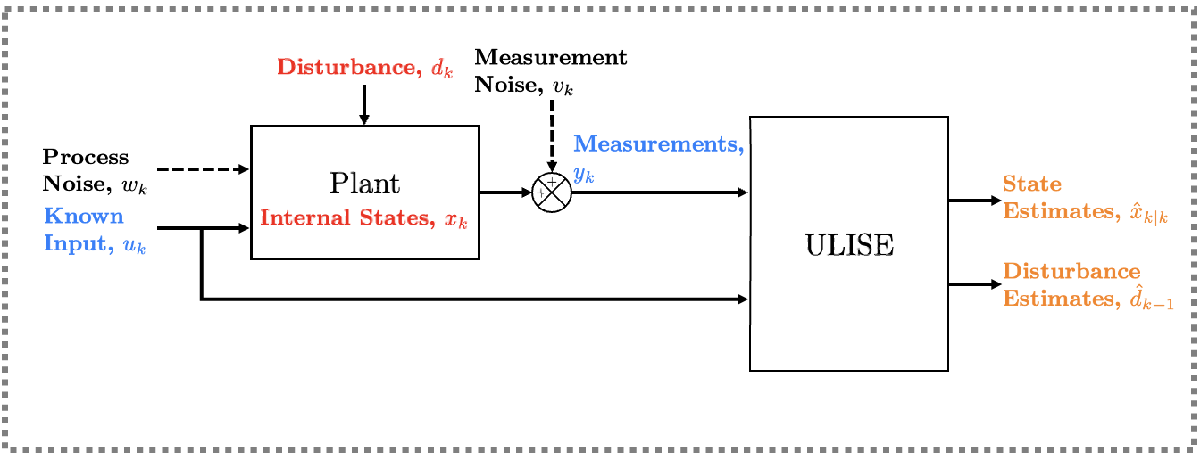

Figure 1: Overview block diagram of a plant and the ULISE filter.

### Example:

- [ULISE for Fault Identification](matlab:open('../Examples/example_ULISE_fault_identification.mlx'))

### Inputs:

### Outputs:

### Assumptions:

- System is linear, time-invariant, and discrete-time.

-  Input arrays u and y must have K columns. If u or y are single column vectors, set K = size(u, 2).

- Initial state estimate $\hat{x}_0$ and covariance $P_{x_0}$ are provided.

- Process and measurement noises $w_k, v_k$ are zero-mean, white Gaussian noise.

- The process and measurement noise covariance must be positive semi-definite matrices i.e. $Q \succeq 0$ and $R \succeq 0$.

### Limitations:

The system must satisfy the following conditions for ULISE to produce unbiased, stable estimates:

**(i) Strong detectability**


$$rank(P(z)) := rank \left( \left[ \matrix{(zI-A) & -G \cr C & H} \right] \right) = n + p, \forall z \in \mathbb{C}, |z| \ge 1$$


**(ii) Zero-step state, One-step Input delay**


$$rank(C_2G_2) = p - p_H$$
   

**(iii) Frequency-Domain Identifiability** 


$$rank \left( \left[ \matrix{(\hat{A}-e^{j \omega}I) & G_2 & \hat{Q}^{1/2} & 0 \cr e^{j \omega}C_2 & 0 & 0 & R_2^{1/2}}\right] \right) = n + l - p_H, \forall \omega \in [0, 2\pi]. $$


where


$$ \hat{A} = A - G_1 \Sigma^{-1} C_1, \hspace{2em} R_2 = \mathbb{E} [ v_2v_2^T] = U_2^T R U_2 \succ 0.$$


If these conditions are not met, ULISE may fail to converge or may require estimating the unknown inputs with more than one step delay. In such cases, an error message is returned. 

*For details, see Theorem 2 (Strong Detectability) and Theorem 6 (Stability) in [**1**].*

### Algorithm: 

The system is given by

$$x_{k+1} = Ax_k + Bu_k + Gd_k + w_k$$,


$$$y_k = Cx_k + Du_k + Hd_k + v_k$$$


where $$w_k$$ and $$v_k
$$ are zero-mean noise with covariance matrices 


$$$\mathbb{E}[w_kw_k^T]=Q, \text{ \hspace{1em}}  \mathbb{E}[v_kv_k^T] = R \text{,  \hspace{0.5em}  and  \hspace{0.5em} } \mathbb{E}[w_kv_k^T] = 0$.$$


ULISE returns the optimal unbiased, minimum-variance estimates using the following principal steps:

- **Partition **$\mathit{\mathbf{H}}$** using SVD:**


$$H = U \Sigma V^T = \left[\matrix{U_1 & U_2}\right] \left[\matrix{ \Sigma & 0 \cr 0 & 0} \right] \left[\matrix{V_1 & V_2}\right]^T$$


            where $\Sigma$ contains the nonzero singular values; $U$ is the left orthogonal matrix; $V$ is the right orthogonal matrix.

            In the case where $H$is full column rank then we can determine the $\hat{d}_k$ directly from $\hat{d}_{1,k} $. Otherwise, some components of $d_k$ are only recoverable with one time step delay, i.e. $\hat{d}_{k-1}$.

- **State prediction, **$\hat{x}_{k|k-1}$**:**

$$\hat{x}_{k|k-1} = A \hat{x}_{k-1|k-1} + B u_{k-1} + G_1 \hat{d}_{1,k-1}$$.

- **Estimate **$$\hat{d}_{2,k-1}$$** and **$$\hat{d}_{k-1}$$**:**


$$$\hat{d}_{2,k-1} = M_{k} \left( z_{2,k} - C_2 \hat{x}_{k|k-1} - D_2 u_k \right)$$$


            where


$$M_k = P^d_{2, k-1} G_2^T C_2^T \tilde{R}_{2,k}^{-1}$$


            and 

$$\hat{d}_{k-1} = V_1\hat{d}_{1,k-1} +  V_2\hat{d}_{2,k-1} $$.

- **State correction, **$\hat{x}^*_{k|k} $**:**

$\hat{x}^*_{k|k} = \hat{x}_{k|k-1} + G_2 \hat{d}_{2,k-1}$.

- **State measurement update, **$\hat{x}_{k|k}$**:**


$$\hat{x}_{k|k} = \hat{x}^*_{k|k} + L_k \left( z_{2,k} - C_2 \hat{x}^*_{k|k} - D_2 u_k \right)$$


            where

$L_k = \left( P^{\star x}_{k | k} C_2^T  - G_2 M_k R_2 \right) \tilde{R}_{2,k}^{\star \dagger}$.

- **Estimate **$\hat{d}_{1,k}$**:** 

$\hat{d}_{1,k} = \Sigma^{-1} \left( z_{1,k} - C_1 \hat{x}_{k|k} - D_1 u_k \right)$.    

*For details on the definitions of the error covariance matrices *$P^d_{2, k-1}, R_2,  \tilde{R}_{2,k}^{ \star \dagger}$ and $P^{\star x}_{k | k}$, see *[**1**]. *

### References:

[1] Yong, S. Z., Zhu, M., & Frazzoli, E. (2013). A unified filter for simultaneous input and state estimation of linear discrete-time stochastic systems. arXiv preprint arXiv:1309.6627. Available at: [https://arxiv.org/abs/1309.6627](https://arxiv.org/abs/1309.6627)

% AUTHOR       : Daniel Lawson
% DATE CREATED : October 9, 2025
% REPOSITORY   : https://github.com/dalawson0/SISE.git